% 加载MAT文件并提取状态空间模型
% S = load("iP01_iV01_iQ01_iX01__P-300m_Q-1000m_V+900m_xi-10000md.mat"); % 加载保存的MAT文件
S = load("iP01_iV04_iQ01_iX02__P-300m_Q-1000m_V+1050m_xi-8947md.mat");
sys = S.sys;                  % 提取状态空间模型 ss(A,B,C,D)

% 取电压端口：v_alpha, v_beta (第1-2个输入)，构建电压到电流的传递函数,sys(输出选择, 输入选择)
sys_v2i = sys(:, 1:2);        % 2输出 × 2输入的系统（电流输出/电压输入）

% 得到导纳矩阵 Y(s) = I/V (2x2 传递函数矩阵)
Y = tf(sys_v2i);              % 转换为传递函数形式
Yaa = Y(1,1)  % 导纳矩阵(1,1)元素：v_alpha到i_alpha的导纳


Yaa =
 
     -38.31 s^7 - 2.767e04 s^6 - 1.732e06 s^5 + 2.492e08 s^4 + 1.572e10 s^3 + 3.309e11 s^2 + 3.002e12 s + 1e13
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 1268 s^7 + 5.133e05 s^6 + 8.959e07 s^5 + 7.161e09 s^4 + 2.503e11 s^3 + 4.24e12 s^2 + 3.451e13 s + 1.083e14
 
连续时间传递函数。


Yab = Y(1,2)  % 导纳矩阵(1,2)元素：v_beta到i_alpha的导纳


Yab =
 
    -243.3 s^7 - 3.313e05 s^6 - 7.794e07 s^5 - 6.706e09 s^4 - 2.39e11 s^3 - 4.076e12 s^2 - 3.325e13 s - 1.045e14
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 1268 s^7 + 5.133e05 s^6 + 8.959e07 s^5 + 7.161e09 s^4 + 2.503e11 s^3 + 4.24e12 s^2 + 3.451e13 s + 1.083e14
 
连续时间传递函数。


Yba = Y(2,1)  % 导纳矩阵(2,1)元素：v_alpha到i_beta的导纳


Yba =
 
     -5.215 s^7 - 7100 s^6 - 2.637e06 s^5 - 3.183e08 s^4 - 1.287e10 s^3 - 2.324e11 s^2 - 1.951e12 s - 6.215e12
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 1268 s^7 + 5.133e05 s^6 + 8.959e07 s^5 + 7.161e09 s^4 + 2.503e11 s^3 + 4.24e12 s^2 + 3.451e13 s + 1.083e14
 
连续时间传递函数。


Ybb = Y(2,2)  % 导纳矩阵(2,2)元素：v_beta到i_beta的导纳


Ybb =
 
    -33.12 s^7 - 2.06e04 s^6 - 6.21e06 s^5 - 7.168e08 s^4 - 2.838e10 s^3 - 5.034e11 s^2 - 4.155e12 s - 1.303e13
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 1268 s^7 + 5.133e05 s^6 + 8.959e07 s^5 + 7.161e09 s^4 + 2.503e11 s^3 + 4.24e12 s^2 + 3.451e13 s + 1.083e14
 
连续时间传递函数。


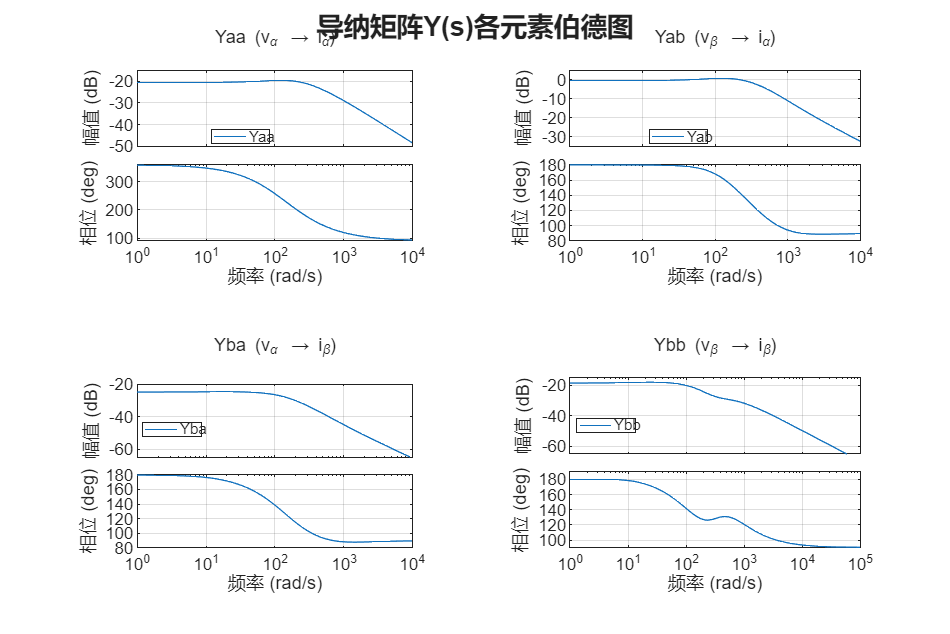


%% 绘制四个导纳元素的伯德图
figure('Color','white','Position',[100,100,1200,800]); % 创建白色背景的大图，方便查看

% 绘制Yaa的伯德图
subplot(2,2,1);
bode(Yaa);
grid on;  % 显示网格，便于读取数值
title('Yaa (v_\alpha \rightarrow i_\alpha)');
legend('Yaa','Location','best');

% 绘制Yab的伯德图
subplot(2,2,2);
bode(Yab);
grid on;
title('Yab (v_\beta \rightarrow i_\alpha)');
legend('Yab','Location','best');

% 绘制Yba的伯德图
subplot(2,2,3);
bode(Yba);
grid on;
title('Yba (v_\alpha \rightarrow i_\beta)');
legend('Yba','Location','best');

% 绘制Ybb的伯德图
subplot(2,2,4);
bode(Ybb);
grid on;
title('Ybb (v_\beta \rightarrow i_\beta)');
legend('Ybb','Location','best');

% 总标题
sgtitle('导纳矩阵Y(s)各元素伯德图','FontSize',16,'FontWeight','bold');

%% ====== 零极点分析 + 自动输出报告（追加在脚本末尾）======

% 过滤阈值（用于去除数值噪声导致的非常小的零/极点）
tol = 1e-8;

% 报告文件名（带时间戳）
ts = datestr(now,'yyyymmdd_HHMMSS');
reportFile = ['Y_zpk_report_' ts '.txt'];

fid = fopen(reportFile,'w');
if fid < 0
    error('无法创建报告文件：%s', reportFile);
end

fprintf(fid, '导纳矩阵 Y(s) 元素零极点分析报告\n');
fprintf(fid, '生成时间: %s\n', datestr(now,'yyyy-mm-dd HH:MM:SS'));
fprintf(fid, '过滤阈值 tol = %.1e\n\n', tol);

% 把四个通道组织起来便于循环
names = {'Yaa','Yab','Yba','Ybb'};
tfs   = {Yaa,  Yab,  Yba,  Ybb };

% 辅助函数：去掉数值上非常接近0的项
cleanVec = @(v) v(abs(v) > tol);

% 辅助函数：判断是否稳定（连续系统：所有极点实部<0；离散则不同，这里按连续处理）
isStableCT = @(p) all(real(p) < -tol);

for k = 1:numel(tfs)
    G = minreal(tfs{k}, tol);         % 尝试做最小实现（去除近似极零抵消）
    
    % 取零/极点/增益（zpk）
    [z, p, k_gain] = zpkdata(G,'v');  % 'v'返回向量
    
    % 清理数值噪声
    z = cleanVec(z);
    p = cleanVec(p);
    
    % 统计右半平面零/极点（连续系统）
    numRHPz = sum(real(z) > tol);
    numRHPp = sum(real(p) > tol);
    
    % 稳定性
    stableFlag = isStableCT(p);
    
    % 找最靠近虚轴的极点（实部最大但仍在左半平面者通常最"慢"）
    if isempty(p)
        p_near = [];
    else
        [~, idx] = max(real(p));   % 实部最大的极点（可能是RHP也可能LHP）
        p_near = p(idx);
    end
    
    % ===== 输出到命令行 =====
    fprintf('\n========== %s ==========\n', names{k});
    fprintf('minreal后模型: \n');
    disp(G);
    fprintf('增益 k = %.6g\n', k_gain);
    fprintf('零点数量: %d, 极点数量: %d\n', numel(z), numel(p));
    fprintf('RHP零点: %d, RHP极点: %d\n', numRHPz, numRHPp);
    fprintf('稳定性(连续): %s\n', ternary(stableFlag,'稳定(所有极点在LHP)','不稳定(存在RHP/虚轴极点)'));
    if ~isempty(p_near)
        fprintf('最靠近虚轴的极点(实部最大): %.6g%+.6gj\n', real(p_near), imag(p_near));
    end
    
    % ===== 写入报告文件 =====
    fprintf(fid, '========== %s ==========\n', names{k});
    fprintf(fid, 'minreal后传递函数(简化表示):\n');
    fprintf(fid, '%s\n', evalc('disp(G)'));
    fprintf(fid, '增益 k = %.12g\n', k_gain);
    fprintf(fid, '零点数量: %d, 极点数量: %d\n', numel(z), numel(p));
    fprintf(fid, 'RHP零点: %d, RHP极点: %d\n', numRHPz, numRHPp);
    fprintf(fid, '稳定性(连续): %s\n', ternary(stableFlag,'稳定(所有极点在LHP)','不稳定(存在RHP/虚轴极点)'));
    if ~isempty(p_near)
        fprintf(fid, '最靠近虚轴的极点(实部最大): %.12g%+.12gj\n', real(p_near), imag(p_near));
    else
        fprintf(fid, '最靠近虚轴的极点: (无极点/或被minreal消去)\n');
    end
    
    % 逐行列出零/极点
    fprintf(fid, '\n-- 零点列表 z --\n');
    if isempty(z)
        fprintf(fid, '(无)\n');
    else
        for ii = 1:numel(z)
            fprintf(fid, '%3d: %.12g%+.12gj\n', ii, real(z(ii)), imag(z(ii)));
        end
    end
    
    fprintf(fid, '\n-- 极点列表 p --\n');
    if isempty(p)
        fprintf(fid, '(无)\n');
    else
        for ii = 1:numel(p)
            fprintf(fid, '%3d: %.12g%+.12gj\n', ii, real(p(ii)), imag(p(ii)));
        end
    end
    
    fprintf(fid, '\n\n');
end


========== Yaa ==========


minreal后模型: 


  tf - 属性:

       Numerator: {[0 -38.3074 -2.2194e+04 1.5203e+06 7.9590e+07 1.0897e+09 4.6681e+09]}
     Denominator: {[1 1.1255e+03 3.5033e+05 3.7129e+07 1.1062e+09 1.2736e+10 5.0545e+10]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



增益 k = -38.3074


零点数量: 5, 极点数量: 6


RHP零点: 1, RHP极点: 0


稳定性(连续): 稳定(所有极点在LHP)


最靠近虚轴的极点(实部最大): -10.1834+0j



========== Yab ==========


minreal后模型: 


  tf - 属性:

       Numerator: {[0 -243.3099 -2.9651e+05 -3.5064e+07 -1.0612e+09 -1.2269e+10 -4.8746e+10]}
     Denominator: {[1 1.1255e+03 3.5033e+05 3.7129e+07 1.1062e+09 1.2736e+10 5.0545e+10]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



增益 k = -243.31


零点数量: 5, 极点数量: 6


RHP零点: 0, RHP极点: 0


稳定性(连续): 稳定(所有极点在LHP)


最靠近虚轴的极点(实部最大): -10.1834+0j



========== Yba ==========


minreal后模型: 


  tf - 属性:

       Numerator: {[0 -5.2147 -6.3549e+03 -1.7180e+06 -5.9278e+07 -7.1720e+08 -2.9004e+09]}
     Denominator: {[1 1.1255e+03 3.5033e+05 3.7129e+07 1.1062e+09 1.2736e+10 5.0545e+10]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



增益 k = -5.21469


零点数量: 5, 极点数量: 6


RHP零点: 0, RHP极点: 0


稳定性(连续): 稳定(所有极点在LHP)


最靠近虚轴的极点(实部最大): -10.1834+0j



========== Ybb ==========


minreal后模型: 


  tf - 属性:

       Numerator: {[0 -33.1211 -1.5873e+04 -3.8709e+06 -1.2983e+08 -1.5339e+09 -6.0790e+09]}
     Denominator: {[1 1.1255e+03 3.5033e+05 3.7129e+07 1.1062e+09 1.2736e+10 5.0545e+10]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



增益 k = -33.1211


零点数量: 5, 极点数量: 6


RHP零点: 0, RHP极点: 0


稳定性(连续): 稳定(所有极点在LHP)


最靠近虚轴的极点(实部最大): -10.1834+0j



fclose(fid);
fprintf('\n零极点分析报告已保存到: %s\n', reportFile);


零极点分析报告已保存到: Y_zpk_report_20260205_121145.txt



%% ====== 小工具：三目运算（MATLAB没有内置）======
function out = ternary(cond, a, b)
if cond
    out = a;
else
    out = b;
end
end

S = load("iP01_iV01_iQ01_iX01__P-300m_Q-1000m_V+900m_xi-10000md.mat");
sys = S.sys;
sys_v2i = sys(:, 1:2);   % 2 outputs (i_alpha,i_beta) × 2 inputs (v_alpha,v_beta)

% 设定频率点（单位 rad/s）
w = logspace(0, 5, 2000);   % 1 ~ 1e5 rad/s, 2000点（按需改）

% 逐频率点计算频响：返回尺寸 [ny, nu, Nw] = [2, 2, length(w)]
Yjw = freqresp(sys_v2i, w);

% 拿出各元素（都是 1×1×Nw，需要 squeeze）
Yaa = squeeze(Yjw(1,1,:));  % i_alpha / v_alpha
Yab = squeeze(Yjw(1,2,:));  % i_alpha / v_beta
Yba = squeeze(Yjw(2,1,:));  % i_beta  / v_alpha
Ybb = squeeze(Yjw(2,2,:));  % i_beta  / v_beta

% 例如画幅值相位
f = w/(2*pi);
figure; semilogx(f, 20*log10(abs(Yaa))); grid on; xlabel('Hz'); ylabel('|Y_{aa}| (dB)');

%% ========================= IEEE Trans 风格：导纳矩阵伯德图 =========================
% 说明：
% 1) 统一 Times New Roman 字体、线宽、图窗尺寸
% 2) 采用 bodeplot + bodeoptions 统一幅相显示风格
% 3) 子图使用 tiledlayout（更像论文排版），减少拥挤
% 4) 网格采用细点线，符合多数 IEEE 文章视觉习惯
% 5) 导出建议用 exportgraphics（矢量 PDF/EPS）
%% ========================= 绘图全局风格（IEEE-like） =========================
% 字体/线宽/坐标轴等统一设置（对 bodeplot 生成的所有 axes 生效）
set(groot,'defaultFigureColor','w');
set(groot,'defaultAxesFontName','Times New Roman');
set(groot,'defaultTextFontName','Times New Roman');
set(groot,'defaultAxesFontSize',10);
set(groot,'defaultTextFontSize',10);
set(groot,'defaultLineLineWidth',1.2);
set(groot,'defaultAxesLineWidth',0.8);
set(groot,'defaultAxesTickDir','out');
set(groot,'defaultAxesBox','on');

%% bodeplot 选项（统一幅相显示格式）
opt = bodeoptions('cstprefs');
opt.FreqUnits        = 'Hz';          % IEEE 论文里常用 Hz（如需 rad/s 改成 'rad/s'）
opt.MagUnits         = 'dB';
opt.PhaseUnits       = 'deg';
opt.PhaseWrapping    = 'on';          % 相位包络（避免跳变太乱，必要时可关）
opt.Grid             = 'on';
opt.XLabel.FontSize  = 10;
opt.YLabel.FontSize  = 10;
opt.Title.FontSize   = 11;
opt.TickLabel.FontSize = 9;

% 网格更"轻"
opt.GridColor        = [0.6 0.6 0.6];
% opt.GridLineStyle    = ':';
% opt.GridAlpha        = 0.35;

% 幅相图的相对布局更紧凑（bode 默认两行轴）
opt.PhaseVisible     = 'on';

%% ========================= 2×2 子图布局（tiledlayout 更像论文） =========================
fig = figure('Units','centimeters','Position',[2 2 18 12]);  % 约 IEEE 单栏宽~8.8cm，双栏~18cm
tl = tiledlayout(fig,2,2,'TileSpacing','compact','Padding','compact');

% —— 子图 1：Yaa
nexttile;
h1 = bodeplot(Yaa,opt);
title('$Y_{\alpha\alpha}(s)$: $v_\alpha \rightarrow i_\alpha$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 2：Yab
nexttile;
h2 = bodeplot(Yab,opt);
title('$Y_{\alpha\beta}(s)$: $v_\beta \rightarrow i_\alpha$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 3：Yba
nexttile;
h3 = bodeplot(Yba,opt);
title('$Y_{\beta\alpha}(s)$: $v_\alpha \rightarrow i_\beta$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% —— 子图 4：Ybb
nexttile;
h4 = bodeplot(Ybb,opt);
title('$Y_{\beta\beta}(s)$: $v_\beta \rightarrow i_\beta$','Interpreter','latex');
set(findall(gcf,'Type','axes'),'FontName','Times New Roman');

% 总标题（论文里一般不需要很大，且不加粗过度）
title(tl,'Admittance Matrix Elements $Y(s)$ (Bode Plots)','Interpreter','latex','FontSize',12);

%% ========================= 细节优化：统一线宽、避免 legend 干扰 =========================
% IEEE 图一般不强制每个子图 legend（除非多曲线对比）
% 若你坚持要 legend，可以开：legend('show') 并控制位置，但 bodeplot 默认不显示 legend

% bodeplot 会生成两条轴（幅值/相位），这里统一线宽等细节
allLines = findall(fig,'Type','line');
set(allLines,'LineWidth',1.2);

% 可选：设置频率范围（按需要改）
% setoptions(h1,'XLim',{[1 1e4]});  % Hz
% setoptions(h2,'XLim',{[1 1e4]});
% setoptions(h3,'XLim',{[1 1e4]});
% setoptions(h4,'XLim',{[1 1e4]});

%% ========================= 导出（推荐矢量） =========================
% IEEE 投稿强烈建议矢量图（PDF/EPS），或 600dpi PNG
% exportgraphics(fig,'Y_matrix_bode.pdf','ContentType','vector');
% exportgraphics(fig,'Y_matrix_bode.png','Resolution',600);

%% 新增：求解阻抗矩阵 Z(s) = V/I = Y(s)⁻¹（导纳矩阵的逆）
% 注意：这里是传递函数矩阵的逆，而非逐元素取倒数
Z = inv(Y);  % 2x2 阻抗矩阵 Z(s) = Y(s)的逆矩阵

% 提取阻抗矩阵的四个元素
Zaa = Z(1,1)  % 阻抗矩阵(1,1)元素：i_alpha到v_alpha的阻抗
Zab = Z(1,2)  % 阻抗矩阵(1,2)元素：i_beta到v_alpha的阻抗
Zba = Z(2,1)  % 阻抗矩阵(2,1)元素：i_alpha到v_beta的阻抗
Zbb = Z(2,2)  % 阻抗矩阵(2,2)元素：i_beta到v_beta的阻抗

%% 绘制四个阻抗元素的伯德图（与导纳布局一致，便于对比）
figure('Color','white','Position',[100,100,1200,800]); % 创建新的绘图窗口

% 绘制Zaa的伯德图
subplot(2,2,1);
bode(Zaa);
grid on;
title('Zaa (i_\alpha \rightarrow v_\alpha)');
legend('Zaa','Location','best');

% 绘制Zab的伯德图
subplot(2,2,2);
bode(Zab);
grid on;
title('Zab (i_\beta \rightarrow v_\alpha)');
legend('Zab','Location','best');

% 绘制Zba的伯德图
subplot(2,2,3);
bode(Zba);
grid on;
title('Zba (i_\alpha \rightarrow v_\beta)');
legend('Zba','Location','best');

% 绘制Zbb的伯德图
subplot(2,2,4);
bode(Zbb);
grid on;
title('Zbb (i_\beta \rightarrow v_\beta)');
legend('Zbb','Location','best');

% 阻抗伯德图总标题
sgtitle('阻抗矩阵Z(s)各元素伯德图','FontSize',16,'FontWeight','bold');

%% 方法1）直接"把传递函数求逆"：Z(s) = inv(Y(s)) = inv(sys_v2i)
% 推荐：对 ss/ltisys 求逆而不是对 tf 求逆（数值通常更稳）
sysY = sys_v2i;           % 电压->电流（导纳） 2x2
sysZ1 = inv(sysY);        % 阻抗系统（电流->电压） 2x2

Z1 = tf(sysZ1);           % 转成传递函数矩阵便于取元素
Z1aa = Z1(1,1);
Z1ab = Z1(1,2);
Z1ba = Z1(2,1);
Z1bb = Z1(2,2);

% 绘制四个阻抗元素的伯德图（2x2）
figure('Color','white','Position',[120,120,1200,800]);

subplot(2,2,1);
bode(Z1aa); grid on;
title('Z1aa (i_\alpha \rightarrow v_\alpha)  [inv(sys)]');

subplot(2,2,2);
bode(Z1ab); grid on;
title('Z1ab (i_\beta \rightarrow v_\alpha)   [inv(sys)]');

subplot(2,2,3);
bode(Z1ba); grid on;
title('Z1ba (i_\alpha \rightarrow v_\beta)   [inv(sys)]');

subplot(2,2,4);
bode(Z1bb); grid on;
title('Z1bb (i_\beta \rightarrow v_\beta)    [inv(sys)]');

sgtitle('阻抗矩阵Z(s)=Y(s)^{-1} 各元素伯德图（方法1：inv(sys)）','FontSize',16,'FontWeight','bold');

%% 方法3）频域上"导纳矩阵点对点求逆"：Z(jw) = inv(Y(jw))
% 选择频率范围（rad/s）；你可按需要改
w = logspace(0,4,2000);              % 1~1e4 rad/s
Yjw = freqresp(sysY, w);             % 2x2xN 复数频响

Zjw = zeros(size(Yjw));
condY = zeros(1,length(w));
badIdx = false(1,length(w));

for k = 1:length(w)
    Yk = Yjw(:,:,k);
    condY(k) = cond(Yk);             % 观察病态程度（越大越接近奇异）

    % 保护：如果矩阵接近奇异，用 pinv 更稳（也可直接报错）
    if rcond(Yk) < 1e-10
        badIdx(k) = true;
        Zjw(:,:,k) = pinv(Yk);       % 近奇异时用伪逆
    else
        Zjw(:,:,k) = inv(Yk);
    end
end

% 提取四个元素频响
Zaa_jw = squeeze(Zjw(1,1,:));
Zab_jw = squeeze(Zjw(1,2,:));
Zba_jw = squeeze(Zjw(2,1,:));
Zbb_jw = squeeze(Zjw(2,2,:));

% 频率换成 Hz 便于阅读（bode常用 rad/s，这里我们自己画）
f = w/(2*pi);

% 画幅值(dB) + 相位(deg)（2x2 子图，每格上下两行）
figure('Color','white','Position',[140,140,1300,850]);

elem = {Zaa_jw,'Z3aa (i_\alpha \rightarrow v_\alpha)'; ...
        Zab_jw,'Z3ab (i_\beta \rightarrow v_\alpha)'; ...
        Zba_jw,'Z3ba (i_\alpha \rightarrow v_\beta)'; ...
        Zbb_jw,'Z3bb (i_\beta \rightarrow v_\beta)'};

for i = 1:4
    Zij = elem{i,1};
    name = elem{i,2};

    subplot(2,2,i);
    yyaxis left
    semilogx(f, 20*log10(abs(Zij))); grid on;
    ylabel('Mag (dB)');

    yyaxis right
    semilogx(f, unwrap(angle(Zij))*180/pi);
    ylabel('Phase (deg)');

    xlabel('Frequency (Hz)');
    title([name '  [freqresp 点对点求逆]']);
end

sgtitle('阻抗矩阵Z(j\omega)=Y(j\omega)^{-1} 幅相曲线（方法3：逐点求逆）','FontSize',16,'FontWeight','bold');

% 可选：画导纳矩阵条件数，看看哪些频点接近奇异
figure('Color','white','Position',[160,160,900,450]);
semilogx(f, log10(condY)); grid on;
xlabel('Frequency (Hz)');
ylabel('log10(cond(Y(j\omega)))');
title('导纳矩阵 Y(j\omega) 条件数（越大越病态）');

% 输出提示：哪些频点用到了 pinv
if any(badIdx)
    fprintf('警告：在 %d 个频点上 Y(jw) 接近奇异，已使用 pinv 替代 inv。\n', nnz(badIdx));
end